% Iqbal Luqmanul Hakim 
% 082111733063
clc; clear all;
x = [0.0 0.5 1.0 1.5 2.0 2.5 3.0 3.5 4.0 4.5 5.0];
y = [1.000 0.994 0.985 0.979 0.977 0.972 0.969 0.967 0.960 0.956 0.952];

jumx = 0;
jumxx = 0;
jumy = 0;
jumxy = 0;

for i = 1:11
    jumx = jumx + x(i);
    jumxx = jumxx + (x(i) ^ 2);
    jumy = jumy + y(i);
    jumxy = jumxy + (y(i) * x(i));
end

A = [11 jumx; jumx jumxx];
B = [jumy; jumxy];

C = inv(A) * B;

disp('Tabel Nilai:');

Tabel Nilai:


disp('--------------------------------------');

--------------------------------------


disp('   x     |    y    |   xy   |   x^2  ');

   x     |    y    |   xy   |   x^2  


disp('--------------------------------------');

--------------------------------------


for i = 1:11
    disp([x(i), y(i), x(i) * y(i), x(i) ^ 2]);
end

     0     1     0     0

    0.5000    0.9940    0.4970    0.2500

    1.0000    0.9850    0.9850    1.0000

    1.5000    0.9790    1.4685    2.2500

    2.0000    0.9770    1.9540    4.0000

    2.5000    0.9720    2.4300    6.2500

    3.0000    0.9690    2.9070    9.0000

    3.5000    0.9670    3.3845   12.2500

    4.0000    0.9600    3.8400   16.0000

    4.5000    0.9560    4.3020   20.2500

    5.0000    0.9520    4.7600   25.0000



disp('--------------------------------------');

--------------------------------------


disp(['JumX  = ', num2str(jumx)]);

JumX  = 27.5


disp(['JumXY = ', num2str(jumxy)]);

JumXY = 26.528


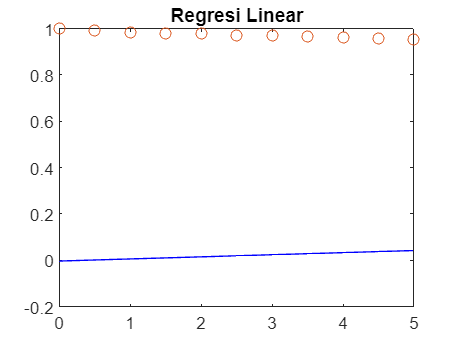


ln_y = zeros(1, 11); % Inisialisasi array untuk menyimpan nilai ln(y(x))

for i = 1:11
    ln_y(i) = log(C(1)) - C(2) * x(i); % Menggunakan rumus ln(y(x)) = ln(a) - bx
end

plot(x, ln_y, 'b', x, y, 'o');
title('Regresi Linear');